# create downsampled vector of all aluminum times without the artifact times


run(params_path)

experiment = auditory_ephys_exp(params_path);

data = load_open_ephys_binary([exp_path,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');
aud_data = data.Data.Data.mapped(32 + mic,:)

% find time samples in video based on whiskers for both whiskers and face
whiskingStart = experiment.Cams.whsiking.csv_start_frame
expLength = length(data.Data.Data.mapped)
whiskingEnd = find(experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)
whiskingVector = [whiskingStart:whiskingEnd]
sampleVector = experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

[~,faceStart] = min(abs(experiment.Cams.face.csv_aligned_frames - sampleVector(1)))
faceEnd = find(experiment.Cams.face.csv_aligned_frames < expLength);
faceEnd = faceEnd(end);
faceVector = [faceStart:faceEnd]

fullSampleVector = sampleVector(1):expLength'

% Extract aluminum times
artifactStart = (experiment.Conditions.artifact_times(2) * 30)
artifactEnd = (experiment.Conditions.artifact_times(1) * 30)
all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]
aluminumTimes = all_times(experiment.Conditions.condition_classification == 1,:)
% create idx vector for aluminum
aluminumInd = []
for al = 1:length(aluminumTimes)
    tempInd = int32(find(sampleVector > aluminumTimes(al,1) & sampleVector < aluminumTimes(al,2)))
    aluminumInd = [aluminumInd;tempInd]
end
full_aluminumInd =[];
for al = 1:length(aluminumTimes)
    tempIndA = int32(find(fullSampleVector > aluminumTimes(al,1) & fullSampleVector < aluminumTimes(al,2)));
    full_aluminumInd = [full_aluminumInd,tempIndA];
end

% create samplevector for aluminum
aluminumVector = int32(sampleVector(aluminumInd))
% create video frame whisker vector
aluminumWhiskerVector = int32(whiskingVector(aluminumInd))'
% create video frame face vector
%aluminumFaceVector = faceVector(aluminumInd)'
fullAluminumVector = int32(fullSampleVector(full_aluminumInd))';%sample location from full data

## **create matrix for prediction with linear regression**

### **The model is a matrix with the following rows as variables and columuns as observations:**

- ** Encoder**

- **whiskingMotion_1**

- **whisking motSVD_0 (10 first)**

- **whisking motSVD_1 (10 first)**

- **faceMotion_1**

- **face motSVD_1 (10 first)**

- **Running from face camera**

**Predictions should be done on a matrix ordered the same why**

**The output will be a vector of the sound from open ephys sampled by the sampleVector and threshold **

% get the sound vector 
%aud_data = data.Data.Data.mapped(34,:)

[b,a] = butter(3,[500]/15000,'high')
aud_data = filtfilt(b,a,double(aud_data))

% get the aluminum sound vector 
%aud_data = aud_data(aluminumVector)

% clean artifacts clipping
aud_data(aud_data > 1000 | aud_data < -1000) = 0;

figure; plot(aud_data(10000000:20000000))

% clean data below threshold
aud_data_env = envelope(aud_data,10,'rms')

aud_data_env =    30.5834   30.1417   31.5766   31.8681   30.4335   31.5044   33.3872   34.2721   30.4681   30.2315   26.8438   25.4375   22.0955   19.7249   20.0521   20.8098   18.3122   19.1990   19.0021   21.6440   21.9105   22.7353   22.9403   25.3279   25.0623   26.4718   25.6571   25.3250   27.4886   26.5585   26.4943   25.8647   27.1635   29.9101   31.8107   30.2543   30.7501   29.5945   27.9816   29.0725   29.0816   32.4273   32.2125   27.3590   24.9060   23.6247   23.6440   29.0797   32.6296   30.8017


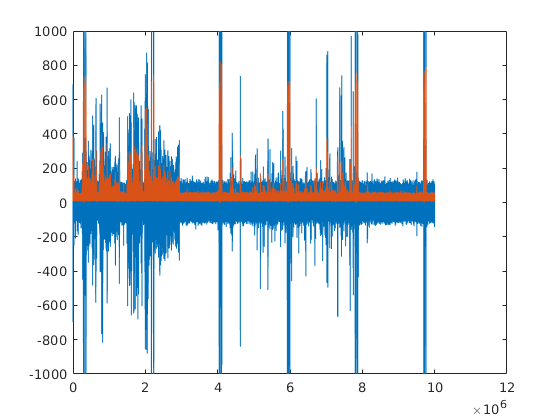

figure; plot(aud_data(10000000:20000000))
hold on; plot(aud_data_env(10000000:20000000))

aud_data = normalize(aud_data_env,'range',[0,1])

aud_data =     0.0372    0.0367    0.0385    0.0388    0.0371    0.0384    0.0407    0.0417    0.0371    0.0368    0.0327    0.0310    0.0269    0.0240    0.0244    0.0253    0.0223    0.0234    0.0231    0.0264    0.0267    0.0277    0.0279    0.0308    0.0305    0.0322    0.0312    0.0308    0.0335    0.0323    0.0323    0.0315    0.0331    0.0364    0.0387    0.0368    0.0374    0.0360    0.0341    0.0354    0.0354    0.0395    0.0392    0.0333    0.0303    0.0288    0.0288    0.0354    0.0397    0.0375


experiment.sound_events.fullSound = aud_data;

aud_data_cleaned = aud_data(fullAluminumVector)

aud_data_cleaned =     0.0442    0.0483    0.0476    0.0490    0.0478    0.0477    0.0487    0.0475    0.0420    0.0443    0.0431    0.0333    0.0331    0.0451    0.0434    0.0434    0.0420    0.0452    0.0500    0.0576    0.0591    0.0575    0.0576    0.0474    0.0543    0.0564    0.0565    0.0539    0.0547    0.0437    0.0453    0.0471    0.0546    0.0588    0.0530    0.0530    0.0541    0.0542    0.0487    0.0484    0.0469    0.0496    0.0415    0.0412    0.0404    0.0380    0.0352    0.0352    0.0371    0.0375


%aud_data_cleaned(aud_data_cleaned < 0.1) = 0

figure; plot(aud_data_cleaned)

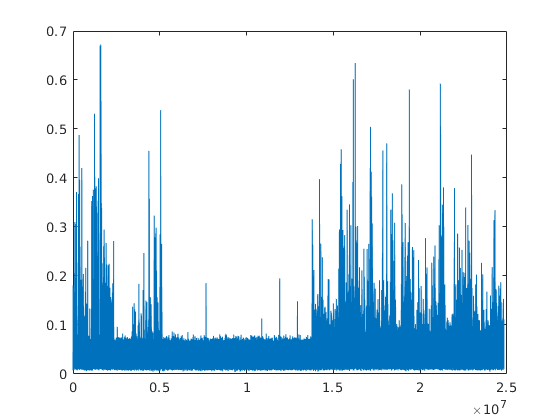

aud_resampled = resample(aud_data(fullSampleVector),1500,30000);

jj = 1:20:length(fullSampleVector)

hh = fullSampleVector(jj)

jj =      1    21    41    61    81   101   121   141   161   181   201   221   241   261   281   301   321   341   361   381   401   421   441   461   481   501   521   541   561   581   601   621   641   661   681   701   721   741   761   781   801   821   841   861   881   901   921   941   961   981


gg = fullAluminumVector(ismember(fullAluminumVector,hh))

hh =        74828       74848       74868       74888       74908       74928       74948       74968       74988       75008       75028       75048       75068       75088       75108       75128       75148       75168       75188       75208       75228       75248       75268       75288       75308       75328       75348       75368       75388       75408       75428       75448       75468       75488       75508       75528       75548       75568       75588       75608       75628       75648       75668       75688       75708       75728       75748       75768       75788       75808


figure; plot(aud_resampled(ismember(hh,fullAluminumVector)))

gg = 1241055×1 int32 column vector
   10437148
   10437168
   10437188
   10437208
   10437228
   10437248
   10437268
   10437288
   10437308
   10437328


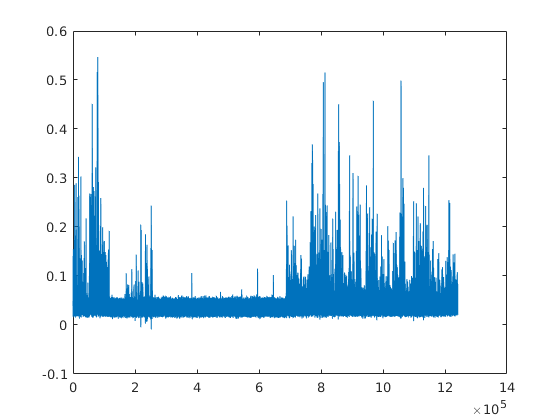

figure;plot(aud_resampled)

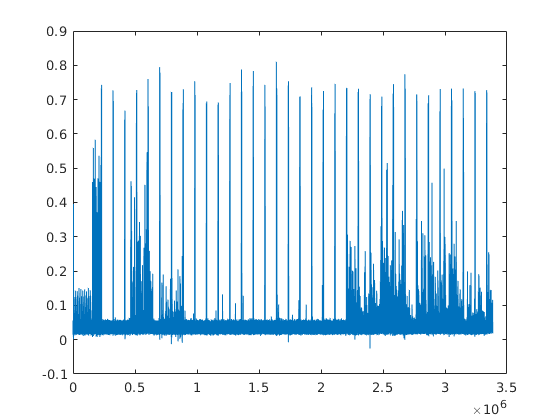

% get encoder data and high pass filter 
encoder_data = data.Data.Data.mapped(32 + encoder,:)

[b,a] = butter(3,[2]/30000,'high')
encoder_data = filtfilt(b,a,double(encoder_data))

% add encoder to the modal and prediction matrices
%modelMatrix = encoder_data(aluminumVector)
%predictionMatrix = encoder_data(sampleVector)
modelMatrix = encoder_data(fullAluminumVector)
predictionMatrix = encoder_data(fullSampleVector)

%use fullAluminumInd
save('experimentPremodel.mat',"predictionMatrix","modelMatrix","experiment","aud_data_cleaned")

clearvars -except fullSampleVector full_aluminumInd fullAluminumVector predictionMatrix modelMatrix whiskingVector

fullSampleVector = int32(fullSampleVector)
whiskingVector = int32(whiskingVector)

% import the whisking moiton vectors
[file,path] = uigetfile();
cd(path)
load(file,'motSVD_1','motion_1')
try
    load(file,'motSVD_2')
catch 
    'no motSVD_2'
end

% Create a matrix of SVD and motion of whisker camera and resample for the
% model creation
motion4Resample = (double(motion_1(whiskingVector))');
motSVD4Resample = (double(motSVD_1(whiskingVector,1:20)));

%resample on a second machine with larger ram
%save('for64Gb.mat',"motion4Resample","motSVD4Resample","fullSampleVector")

%load resampled data
%load();

%calculate the resampling ratio
newSF = round(length(fullSampleVector)/length(motion4Resample)*400);

clear motion_1 motSVD_1 

motionResampled = single(resample(motion4Resample,newSF,400));

SVDresampled = ((zeros(length(motionResampled),20)));

for i =1:20
    SVDresampled(:,i) = (resample(motSVD4Resample(:,i),newSF,400));
end

%motionResampled = single(motionResampled);
SVDresampled = single(SVDresampled);

SVDresampled = SVDresampled(1:length(fullSampleVector),:);

motionResampled = motionResampled(1:length(fullSampleVector));

clear motion4Resample motSVD4Resample

clearvars -except fullSampleVector full_aluminumInd fullAluminumVector predictionMatrix modelMatrix aud_data_cleaned SVDresampled motionResampled

modelMatrix = single(modelMatrix);

predictionMatrix = single(predictionMatrix);

aud_data_cleaned = single(aud_data_cleaned);
%fullSampleVector = single(fullSampleVector);

% Create model metrices after resampling video data
modelMatrix(2,:) = motionResampled(full_aluminumInd);
SVDmodel = SVDresampled(full_aluminumInd,:);

modelMatrix(3:22,:) = SVDmodel';

clear SVDmodel

save('modelMatrices.mat',"modelMatrix","aud_data_cleaned","full_aluminumInd","fullAluminumVector",'fullSampleVector','-v7.3')

save('forPrediction.mat',"predictionMatrix","motionResampled","SVDresampled",'-v7.3')

% save('whisking_resampled.mat',"SVDresampled","motionResampled","fullSampleVector",'newSF','-v7.3')

% if ~isempty(motSVD_0)% add motion and motSVDs to the modal and prediciton matrices
%     modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
%     predictionMatrix(2,:) = motion_1(whiskingVector)
%     modelMatrix(3:12,:) = motSVD_0(aluminumWhiskerVector,1:10)'
%     predictionMatrix(3:12,:) = motSVD_0(whiskingVector,1:10)'
%     modelMatrix(13:22,:) = motSVD_1(aluminumWhiskerVector,1:10)'
%     predictionMatrix(13:22,:) = motSVD_1(whiskingVector,1:10)'
%     ind = 23
% elseif exist('motSVD_2')
%     modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
%     predictionMatrix(2,:) = motion_1(whiskingVector)
%     modelMatrix(3:12,:) = motSVD_1(aluminumWhiskerVector,1:10)'
%     predictionMatrix(3:12,:) = motSVD_1(whiskingVector,1:10)'
%     modelMatrix(13:22,:) = motSVD_2(aluminumWhiskerVector,1:10)'
%     predictionMatrix(13:22,:) = motSVD_2(whiskingVector,1:10)'
%     ind = 23
% else
%     modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
%     predictionMatrix(2,:) = motion_1(whiskingVector)
%     modelMatrix(3:22,:) = motSVD_1(aluminumWhiskerVector,1:20)'
%     predictionMatrix(3:22,:) = motSVD_1(whiskingVector,1:20)'
%     ind = 13
% end


% import data from face video
% clear motion_1 motion_0 motSVD_1 motSVD_0
% [file,path] = uigetfile();
% cd(path)
% load(file, 'motSVD_1','motion_1','running_0')

% % add motion and motSVDs to the modal and prediciton matrices
% modelMatrix(ind,:) = motion_1(aluminumFaceVector)
% predictionMatrix(ind,:) = motion_1(faceVector)
% modelMatrix(ind+1:ind+10,:) = motSVD_1(aluminumFaceVector,1:10)'
% predictionMatrix(ind+1:ind+10,:) = motSVD_1(faceVector,1:10)'
% modelMatrix(ind+11:ind+12,:) = running_0(aluminumFaceVector,1:2)'
% predictionMatrix(ind+11:ind+12,:) = running_0(faceVector,1:2)'

% save the model and prediction vectors 
save('model_matrices.mat','experiment','modelMatrix',"aud_data_cleaned",'predictionMatrix','sampleVector','aluminumWhiskerVector')

% load model and prediction if needed
cd('/home/ben/Z/FVB/270721/849')  

                 
load('model_matrices.mat')

% create traintest spli idx for testing model
modelPart = cvpartition(length(modelMatrix),"HoldOut",0.1)
idxTrain = training(modelPart)
idxTest = test(modelPart)

% split data to train test
modelTrain = (modelMatrix(:,idxTrain))
modelTest = (modelMatrix(:,idxTest))

aud_data_Train = (aud_data_cleaned(idxTrain))
aud_data_test = (aud_data_cleaned(idxTest))

%aud_data_cleaned = normalize(aud_data_cleaned,'range')

% savr model to the experiment object
experiment.predictionModel = trainedModel;

% Get predictions from regression learner (bagged tree ensamble)
y = trainedModel.predictFcn(predictionMatrix)

% find all y values aboe threshold and find the start of each event 

[times] = event_detection(experiment.sound_events.fullSound,30000*0.4)



% find events sample time
times_prediction = times
times = sampleVector(times);

experiment.predictedSound.y = y
experiment.predictedSound.sampleVector = sampleVector
experiment.predictedSound.events.all = times_prediction

% Add the events top the experiment object
experiment.sound_events.all = times

artifactStart = experiment.Conditions.artifact_times(2) * 30
artifactEnd = experiment.Conditions.artifact_times(1) * 30
all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]

all_times = all_times(1:22,:)

times = experiment.sound_events.all;
times_prediction = experiment.predictedSound.events.all

`Divide the events to the experiment condition`

% Aluminum times
aluminumTimes = all_times(experiment.Conditions.condition_classification(1:18) == 1,:)
aluminumEvents = []
experiment.predictedSound.events.aluminum = [];
for al = 1:length(aluminumTimes)
    tempEvents = times(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))
    tempPredict = times_prediction(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))'
    aluminumEvents = [aluminumEvents;tempEvents]
    experiment.predictedSound.events.aluminum = [experiment.predictedSound.events.aluminum;tempPredict]
end

% non times
nonTimes = all_times(experiment.Conditions.condition_classification(1:18) == 3,:)
experiment.predictedSound.events.non = [];
nonEvents = []
for non = 1:length(nonTimes)
    tempInd = times(find(times > nonTimes(non,1) & times < nonTimes(non,2)))
    tempPredict = times_prediction(find(times > nonTimes(non,1) & times < nonTimes(non,2)))'
    nonEvents = [nonEvents;tempInd]
    experiment.predictedSound.events.non = [experiment.predictedSound.events.non;tempPredict];
end

% muted times
mutedTimes = all_times(experiment.Conditions.condition_classification(1:18) == 2,:)
experiment.predictedSound.events.muted = [];
mutedEvents = []
for mut = 1:length(mutedTimes)
    tempInd = times(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))
    tempPredict = times_prediction(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))'
    mutedEvents = [mutedEvents;tempInd]
    experiment.predictedSound.events.muted = [experiment.predictedSound.events.muted;tempPredict];
end

timeWind = 1;
numBins = 20;

rasters_aluminum = {}
psth_aluminum = []
for un = 1:length(experiment.Units.good.id)
    rasters_aluminum{un} = createRaster(aluminumEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])
    psth_aluminum(un,:) = psth(rasters_aluminum{un},numBins);
end

rasters_muted = {}
psth_muted = []
for un = 1:length(experiment.Units.good.id)
    rasters_muted{un} = createRaster(mutedEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_muted(un,:) = psth(rasters_muted{un},numBins);
end

rasters_non = {}
psth_non = []
for un = 1:length(experiment.Units.good.id)
    rasters_non{un} = createRaster(nonEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_non(un,:) = psth(rasters_non{un},numBins);
end

rasters_aluminumMua = {}
psth_aluminumMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_aluminumMua{un} = createRaster(aluminumEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])
    psth_aluminumMua(un,:) = psth(rasters_aluminumMua{un},numBins);
end

rasters_mutedMua = {}
psth_mutedMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_mutedMua{un} = createRaster(mutedEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_mutedMua(un,:) = psth(rasters_mutedMua{un},numBins);
end

rasters_nonMua = {}
psth_nonMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_nonMua{un} = createRaster(nonEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_nonMua(un,:) = psth(rasters_nonMua{un},numBins);
end

psth_aluminumAll = [psth_aluminum;psth_aluminumMua]

psth_mutedAll = [psth_muted;psth_mutedMua]
psth_nonAll = [psth_non;psth_nonMua]

aud_units = find(experiment.evokedEvents.pVal(:,2) == 1);
[~,time_vector] = psth(rasters_non{1},numBins);

mutSTD = std(psth_mutedAll(aud_units,:))/sqrt(length(aud_units))
alumSTD = std(psth_aluminumAll(aud_units,:))/sqrt(length(aud_units))
nonSTD = std(psth_nonAll(aud_units,:))/sqrt(length(aud_units))

figure; 
hold on     

plot(time_vector,mean(psth_aluminumAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Aluminum)
errorbar(time_vector,mean(psth_aluminumAll(aud_units,:)),alumSTD,'LineWidth',0.1,'Color',experiment.color.Aluminum)
hold on
plot(time_vector,mean(psth_mutedAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Muted)
errorbar(time_vector,mean(psth_mutedAll(aud_units,:)),mutSTD,'LineWidth',0.1,'Color',experiment.color.Muted)
plot(time_vector,mean(psth_nonAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.noObject)
errorbar(time_vector,mean(psth_nonAll(aud_units,:)),nonSTD,'LineWidth',0.1,'Color',experiment.color.noObject)

meanSound.aluminumMean = meanMatrix(experiment.predictedSound.events.aluminum,1,400)
figure; plot(mean(y(meanSound.aluminumMean)))
hold on
meanSound.mutedMean = meanMatrix(experiment.predictedSound.events.muted,1,400)
plot(mean(y(meanSound.mutedMean)))
meanSound.nonMean = meanMatrix(experiment.predictedSound.events.non,1,400)
plot(mean(y(meanSound.nonMean)))

meanSound.aluminumMean = meanMatrix(aluminumEvents,1,30000);
figure; plot(mean(experiment.sound_events.fullSound(meanSound.aluminumMean)));
hold on;
meanSound.mutedMean = meanMatrix(mutedEvents,1,30000);
plot(mean(experiment.sound_events.fullSound(meanSound.mutedMean)));
meanSound.nonMean = meanMatrix(nonEvents,1,30000)
plot(mean(experiment.sound_events.fullSound(meanSound.nonMean)));

experiment.sound_events.aluminum = aluminumTimes;
experiment.sound_events.muted = mutedTimes;
experiment.sound_events.non = nonTimes;
experiment.PSTHs.alum = psth_aluminumAll;
experiment.PSTHs.muted = psth_mutedAll;
experiment.PSTHs.non = psth_nonAll;
%experiment.PSTHs.audUnits = aud_units;
experiment.PSTHs.time_vector = time_vector;

experiment.sound_events.aluminumEvents = aluminumEvents;
experiment.sound_events.mutedEvents = mutedEvents;
experiment.sound_events.nonEvents = nonEvents;

%params = '/home/ben/Z/Parameters_files/FVB/FVB103_270721_849.m';
run(params)

save([expName,'.mat'],'experiment')